data_load = load("id_data\IBR=43_u=0.02.mat");
h = data_load.h;

type1_load = load("COI_models\CEN_type1_para.mat");
T_mpc = type1_load.id_Tmpc;

type2_1_load = load("COI_models\CEN_type2_1_para.mat");
M = type2_1_load.id_M;
D = type2_1_load.id_D;
R_sg = type2_1_load.id_Rsg;
T_sg = type2_1_load.id_Tsg;

R_c = type2_1_load.id_Rc;
T_c = type2_1_load.id_Tc;
K_mpc = type2_1_load.id_Kmpc;
K_dis = type2_1_load.id_Kdis;

L = type2_1_load.id_L;
beta = type2_1_load.id_beta;

params = {M; D; R_sg; T_sg; R_c; T_c; T_mpc; K_mpc; K_dis; L; beta};
init_sys = idgrey(@ssm,params,'c');

%Min
init_sys.Structure.Parameters(1).Minimum = 0;
init_sys.Structure.Parameters(2).Minimum = 0;
init_sys.Structure.Parameters(3).Minimum = 0;
init_sys.Structure.Parameters(4).Minimum = 0;
init_sys.Structure.Parameters(5).Minimum = 0;
init_sys.Structure.Parameters(6).Minimum = 0;
init_sys.Structure.Parameters(7).Minimum = 0;
init_sys.Structure.Parameters(8).Minimum = 0;
init_sys.Structure.Parameters(9).Minimum = 0;


%Max
init_sys.Structure.Parameters(10).Maximum = 0;

power_sys = init_sys;

%Sequential u&d PRBS Training
nummertjes = [1,2,3];

for nummertje = nummertjes
    data_train = get_data("id_data\du=PRBS_"+nummertje+".mat");
    opt = greyestOptions('SearchMethod','lsqnonlin', 'Display', 'on');
    opt.SearchOptions.MaxIterations = 50;
    power_sys = greyest(data_train, power_sys, opt);
    disp("Done with: "+nummertje)
end

Done with: 1


Done with: 2


Done with: 3


Done with: 1


Done with: 2


Done with: 3


Done with: 21


Done with: 8


Done with: 16


Done with: 5


Done with: 20


Done with: 9


Done with: 17


Done with: 0


%Parallel PRBS Training
%Load train data
data_u1 = get_data("id_data\IBR=43_u=0.02.mat");
data_u2 = get_data("id_data\IBR=43_u=0.03.mat");
data_u3 = get_data("id_data\IBR=43_u=0.04.mat");

data_u4 = get_data("id_data\IBR=44_u=0.02.mat");
data_u5 = get_data("id_data\IBR=44_u=0.03.mat");
data_u6 = get_data("id_data\IBR=44_u=0.04.mat");

data_u7 = get_data("id_data\IBR=52_u=0.02.mat");
data_u8 = get_data("id_data\IBR=52_u=0.03.mat");
data_u9 = get_data("id_data\IBR=52_u=0.04.mat");

data_u10 = get_data("id_data\IBR=53_u=0.02.mat");
data_u11 = get_data("id_data\IBR=53_u=0.03.mat");
data_u12 = get_data("id_data\IBR=53_u=0.04.mat");

data_u13 = get_data("id_data\IBR=54_u=0.02.mat");
data_u14 = get_data("id_data\IBR=54_u=0.03.mat");
data_u15 = get_data("id_data\IBR=54_u=0.04.mat");

data_u16 = get_data("id_data\IBR=55_u=0.02.mat");
data_u17 = get_data("id_data\IBR=55_u=0.03.mat");
data_u18 = get_data("id_data\IBR=55_u=0.04.mat");

data_u19 = get_data("id_data\IBR=56_u=0.02.mat");
data_u20 = get_data("id_data\IBR=56_u=0.03.mat");
data_u21 = get_data("id_data\IBR=56_u=0.04.mat");

data_u22 = get_data("id_data\IBR=57_u=0.02.mat");
data_u23 = get_data("id_data\IBR=57_u=0.03.mat");
data_u24 = get_data("id_data\IBR=57_u=0.04.mat");

data_d1 = get_data("id_data\loc=21_d=0.2.mat");
data_d2 = get_data("id_data\loc=21_d=0.3.mat");
data_d3 = get_data("id_data\loc=8_d=0.2.mat");
data_d4 = get_data("id_data\loc=8_d=0.3.mat");
data_d5 = get_data("id_data\loc=16_d=0.2.mat");
data_d6 = get_data("id_data\loc=16_d=0.3.mat");
data_d7 = get_data("id_data\loc=5_d=0.2.mat");
data_d8 = get_data("id_data\loc=5_d=0.3.mat");
data_d9 = get_data("id_data\loc=20_d=0.2.mat");
data_d10 = get_data("id_data\loc=20_d=0.3.mat");
data_d11 = get_data("id_data\loc=9_d=0.2.mat");
data_d12 = get_data("id_data\loc=9_d=0.3.mat");
data_d13 = get_data("id_data\loc=17_d=0.2.mat");
data_d14 = get_data("id_data\loc=17_d=0.3.mat");
data_d15 = get_data("id_data\loc=0_d=0.2.mat");
data_d16 = get_data("id_data\loc=0_d=0.3.mat");

data_prbs1 = get_data("id_data\u=PRBS_1.mat");
data_prbs2 = get_data("id_data\u=PRBS_2.mat");
data_prbs3 = get_data("id_data\u=PRBS_3.mat");
data_prbs4 = get_data("id_data\u=PRBS_4.mat");
data_prbs5 = get_data("id_data\u=PRBS_5.mat");
data_prbs6 = get_data("id_data\u=PRBS_6.mat");
data_prbs7 = get_data("id_data\u=PRBS_7.mat");
data_prbs8 = get_data("id_data\u=PRBS_8.mat");
data_prbs9 = get_data("id_data\u=PRBS_9.mat");
data_prbs10 = get_data("id_data\u=PRBS_10.mat");

data_train = merge(data_u1, data_u2, data_u3, data_u4, data_u5, data_u6, data_u7, data_u8, data_u9, data_u10, data_u11, data_u12, data_u13, data_u14, data_u15, data_u16, data_u17, data_u18, data_u19, data_u20, data_u21, data_u22, data_u23, data_u24, data_d1, data_d2, data_d3, data_d4, data_d5, data_d6, data_d7, data_d8, data_d9, data_d10, data_prbs1, data_prbs2, data_prbs3, data_prbs4, data_prbs5, data_prbs6, data_prbs7, data_prbs8, data_prbs9, data_prbs10);


%Free
power_sys.Structure.Parameters(1).Free = true;
power_sys.Structure.Parameters(2).Free = true;
power_sys.Structure.Parameters(3).Free = true;
power_sys.Structure.Parameters(4).Free = true;
power_sys.Structure.Parameters(5).Free = true;
power_sys.Structure.Parameters(6).Free = true;
power_sys.Structure.Parameters(7).Free = true;
power_sys.Structure.Parameters(8).Free = true;
power_sys.Structure.Parameters(9).Free = true;
power_sys.Structure.Parameters(10).Free = true;
power_sys.Structure.Parameters(11).Free = true;


opt = greyestOptions('SearchMethod','lsqnonlin', 'Display', 'on');
opt.SearchOptions.MaxIterations = 30;
power_sys = greyest(data_train, power_sys, opt);

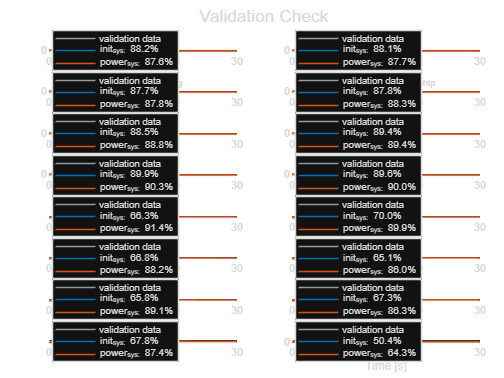

%validation

data_val1 = get_data("id_data\loc=5_d=0.3.mat");
%data_val1 = get_data("id_data\IBR=53_u=0.02.mat");
%data_val1 = get_data("id_data\u=PRBS_14.mat");
%data_val1 = get_data("id_data\du=PRBS_7.mat");

y_meas = data_val1.OutputData;
u_val  = data_val1.InputData;
t      = data_val1.SamplingInstants;

init_sysd = c2d(idss(init_sys),h,'zoh');
y_hat_init = sim(init_sysd, u_val);
y_hat_id = sim(power_sys, u_val);

fit_init = zeros(1,16);
fit_id   = zeros(1,16);

plot_idx = 1:16;
for k = 1:16
    yk = y_meas(:,plot_idx(k));
    fit_init(k) = 100 * (1 - norm(yk - y_hat_init(:,plot_idx(k))) / norm(yk - mean(yk)));
    fit_id(k)   = 100 * (1 - norm(yk - y_hat_id(:,plot_idx(k)))   / norm(yk - mean(yk)));
end

RGB = orderedcolors("gem");

figure
tiledlayout(8,2,'TileSpacing','compact','Padding','compact')

for i = 1:16
    nexttile
    hold on
    plot(t, y_meas(:,plot_idx(i)), 'Color',[0.6 0.6 0.6])
    plot(t, y_hat_init(:,plot_idx(i)), 'Color', RGB(1,:))
    plot(t, y_hat_id(:,plot_idx(i)), 'Color', RGB(2,:))
    grid on
    legend({'validation data', sprintf('init_sys: %.1f%%', fit_init(i)), sprintf('power_sys: %.1f%%', fit_id(i))}, 'Location','best')
    %title(data_val1.OutputName{freq_idx(i)})
    title(sprintf('%s', data_val1.OutputName{plot_idx(i)}))
    ylabel('y')
    hold off
end

xlabel('Time [s]')
sgtitle('Validation Check')

% Identified physical values

params_id = getpar(power_sys, 'value');

id_M = params_id(1:8)'

id_M =     0.8635    0.1955    0.7167    0.7011    0.0200    0.0040    0.0329    0.0293


id_D = params_id(9:16)'

id_D =     0.1583    0.1814    0.0025    0.0215    0.0005    0.1188    0.2398    0.6951


id_Rsg = params_id(17)

id_Rsg = 5.6952

id_Tsg = params_id(18)

id_Tsg = 5.7942

id_Rc = params_id(19:26)'

id_Rc =     5.5577    5.4889    5.4782    5.4513    5.5314    3.9668    3.9978    3.9499


id_Tc = params_id(27:34)'

id_Tc =     0.1135    0.0915    0.0128    0.0182    0.0149    0.0239    0.0042    0.0122


id_Tmpc = params_id(35:42)'

id_Tmpc =     0.8857    0.8766    0.8804    0.6825    0.6993    0.6003    0.8825    0.7606


id_Kmpc = params_id(43:50)'

id_Kmpc =     4.0542    4.9665   35.7519   24.7283   30.3865   25.8478  150.8239   50.9225


id_Kdis = params_id(51:58)'

id_Kdis =     0.3869    0.4444    0.3727    0.3341    0.4638    1.1781    0.3995    2.1905


id_L = params_id(59:69)'

id_L =    -6.9468   -3.4626   -8.0550   -0.2036   -2.7651   -4.3966   -1.5821   -6.2945  -21.2419   -9.9939   -0.0023


id_beta = params_id(70:77)'

id_beta =     9.0153    1.5714    8.5488    9.3837   -0.1776   -0.0673    0.0390   -3.3940




save("COI_models\CEN_type2_2_para.mat", "id_M", "id_D", "id_Rsg", "id_Tsg", "id_Rc", "id_Tc", "id_Kmpc", "id_beta", "id_L", "id_Kdis", "id_Tmpc")


power_sys_ssm = idss(power_sys);
A_ssm = power_sys_ssm.A;
B_ssm = power_sys_ssm.B;
C_ssm = power_sys_ssm.C;
D_ssm = power_sys_ssm.D;

save("COI_models\CEN_type2_2_model.mat",'A_ssm','B_ssm','C_ssm','D_ssm')
 


function [A,B,C,Dsys] = ssm(M, D, R_sg, T_sg, R_c, T_c, T_mpc, K_mpc, K_dis, L, beta, h)
        
    A11 = zeros(8,8);
    A12 = eye(8);
    A13 = zeros(8,1);
    A14 = zeros(8,8);
    A15 = zeros(8,8);
 
    Lap = [-L(1)-L(2),0,L(1),0,0,L(2),0,0; 0,-L(3)-L(4),L(3),0,L(4),0,0,0; L(1),L(3),-L(1)-L(3)-L(5)-L(6),0,L(5),L(6), 0, 0; 0,0,0,-L(7)-L(8),0,0,L(7),L(8); 0,L(4),L(5),0,-L(4)-L(5)-L(9),0,L(9),0; L(2),0,L(6),0,0,-L(2)-L(6)-L(10),0,L(10); 0,0,0,L(7),L(9),0,-L(7)-L(9)-L(11),L(11); 0,0,0,L(8),0,L(10),L(11),-L(8)-L(10)-L(11)];

    A21 = -diag(1./M) * Lap;
    A22 = diag([-D(1)/M(1), -D(2)/M(2), -D(3)/M(3), -D(4)/M(4), -D(5)/M(5), -D(6)/M(6), -D(7)/M(7), -D(8)/M(8)]);
    A23 = [beta(1)/M(1); beta(2)/M(2); beta(3)/M(3); beta(4)/M(4); beta(5)/M(5); beta(6)/M(6); beta(7)/M(7); beta(8)/M(8)];
    A24 = [1/M(1)*ones(1,3), 0, 1/M(1), zeros(1,3); zeros(1,3), 1/M(2), zeros(1,4); zeros(1,5), 1/M(3)*ones(1,2), 0; zeros(1,7), 1/M(4); zeros(4,8)];
    A25 = zeros(8,8);

    A31 = zeros(1,8);
    A32 = -1/(T_sg*R_sg)*(1/sum(M))*M;
    A33 = -1/T_sg;
    A34 = zeros(1,8);
    A35 = zeros(1,8);
    
    A41 = zeros(8,8);
    A42 = [-1/(T_c(1)*R_c(1)),zeros(1,7);-1/(T_c(2)*R_c(2)),zeros(1,7);-1/(T_c(3)*R_c(3)),zeros(1,7);0,-1/(T_c(4)*R_c(4)),zeros(1,6);-1/(T_c(5)*R_c(5)),zeros(1,7);0,0,-1/(T_c(6)*R_c(6)),zeros(1,5);0,0,-1/(T_c(7)*R_c(7)),zeros(1,5);zeros(1,3),-1/(T_c(8)*R_c(8)),zeros(1,4)];
    A43 = zeros(8,1);
    A44 = diag([-1/T_c(1), -1/T_c(2), -1/T_c(3), -1/T_c(4), -1/T_c(5), -1/T_c(6), -1/T_c(7), -1/T_c(8)]);
    A45 = diag(K_mpc);

    A51 = zeros(8,8);
    A52 = zeros(8,8);
    A53 = zeros(8,1);
    A54 = zeros(8,8);
    A55 = diag([-1/T_mpc(1), -1/T_mpc(2), -1/T_mpc(3), -1/T_mpc(4), -1/T_mpc(5), -1/T_mpc(6), -1/T_mpc(7), -1/T_mpc(8)]);

    A = [A11, A12, A13, A14, A15; A21, A22, A23, A24, A25; A31, A32, A33, A34, A35; A41, A42, A43, A44, A45; A51, A52, A53, A54, A55];
    
    Bd = [zeros(8,1); -K_dis'; zeros(17,1)];
    Bu = [zeros(25,8); diag([1/T_mpc(1), 1/T_mpc(2), 1/T_mpc(3), 1/T_mpc(4), 1/T_mpc(5), 1/T_mpc(6), 1/T_mpc(7), 1/T_mpc(8)])];
    B = [Bd, Bu];

    C = [zeros(8,8), eye(8), zeros(8,17); zeros(8,17), eye(8), zeros(8,8)];
    Dsys = zeros(16,9);
end



function [data_loaded] = get_data(name)
    S = load(name);
    h = S.h;
    d_1 = S.d_1 + S.d_2 + S.d_3 + S.d_4 + S.d_5 + S.d_6 + S.d_7 + S.d_8;
    u_1 = S.Pmpc_43;
    u_2 = S.Pmpc_44;
    u_3 = S.Pmpc_52;
    u_4 = S.Pmpc_53;
    u_5 = S.Pmpc_54;
    u_6 = S.Pmpc_55;
    u_7 = S.Pmpc_56;
    u_8 = S.Pmpc_57;
    y_1 = S.f_bus_28;
    y_2 = S.f_bus_11;
    y_3 = S.f_bus_22;
    y_4 = S.f_bus_21;
    y_5 = S.f_bus_26;
    y_6 = S.f_bus_12;
    y_7 = S.f_bus_23;
    y_8 = S.f_bus_2;
    y_9 = S.Pe_43;
    y_10 = S.Pe_44;
    y_11 = S.Pe_52;
    y_12 = S.Pe_53;
    y_13 = S.Pe_54;
    y_14 = S.Pe_55;
    y_15 = S.Pe_56;
    y_16 = S.Pe_57;
    t_1 = S.t;
    data_loaded = iddata([y_1, y_2, y_3, y_4, y_5, y_6, y_7, y_8, y_9, y_10, y_11, y_12, y_13, y_14, y_15, y_16], [d_1, u_1, u_2, u_3, u_4, u_5, u_6, u_7, u_8], h);
    data_loaded.OutputName = {'f_28_Maasvlakte', 'f_11_Borselle', 'f_22_Geertruidenberg', 'f_21_EemshavenOudschip', 'f_26_Maasbracht', 'f_12_Beverwijk', 'f_23_Hengelo', 'f_2_Hessenweg', 'P_c43', 'P_c44', 'P_c52', 'P_c53', 'P_c54', 'P_c55', 'P_c56', 'P_c57'};
    data_loaded.InputName = {'P_dis', 'Pmpc43', 'Pmpc44', 'Pmpc52', 'Pmpc53', 'Pmpc54', 'Pmpc55', 'Pmpc56', 'Pmpc57' };
    data_loaded.Tstart = 0;
    data_loaded.TimeUnit = 's';
end